clear all
syms x
fsym = 1.4.*exp(x).*(x-2).^2+0.9.*x+1;
%fsym = exp(x).*sin(x-2.4)+x^2;
%fsym = (x-1).^2;
%fsym = -(x-1).^2+1;
fplot(fsym,[0 5])
a=gca;
xlabel('x')
ylabel('f(x)')
title('Funkcija kojoj se traži optimum')
grid on
xL=0;
xU=5;
%x0=rand*2.2; %početna točka
x0=rand*5; %početna točka
hold on
plot(x0,double(vpa(subs(fsym,x,x0))),'*','color','r')
text(x0,double(vpa(subs(fsym,x,x0))),'x0-početna')
eps=0.0001; %tražena točnost od f(x)
n=100; %broj iteracija

fder = diff(fsym);
fder2 = diff(fsym,2);
fder3 = diff(fsym,3);
fder4 = diff(fsym,4);
m1 = double(vpasolve(fder2 == 0, x, [xL xU])); %traženje minimuma prve derivacije
M2 = double(vpasolve(fder3 == 0, x, [xL xU])); %traženje maximuma druge derivacije
min=false;
max=false;
if double(vpa(subs(fder3,x,m1))) > 0
    min1=double(vpa(subs(fder,x,m1)));
    min=true;
end
if double(vpa(subs(fder4,x,M2))) < 0
    max2=double(vpa(subs(fder2,x,M2)));
    max=true;
end

if isempty(m1)==1 || min==false 
    donja=double(vpa(subs(fder,x,xL)));
    gornja=double(vpa(subs(fder,x,xU)));
    if donja<=gornja
        min1=donja;
    else
        min1=gornja;
    end
end


if isempty(M2)==1 || max==false
    donja1=double(vpa(subs(fder2,x,xL)));
    gornja1=double(vpa(subs(fder2,x,xU)));
    if donja1<=gornja1
        max2=donja1;
    else
        max2=gornja1;
    end
end

stop = sqrt(abs(2*min1*eps/max2)); %kriterij zaustavljanja

X= double.empty;
X(1)=0;
X(2)=x0;
der0 = double(vpa(subs(fder,x,x0)));

for i=3:n
    der(i-1) = double(vpa(subs(fder,x,X(i-1))));
    der2(i-1) = double(vpa(subs(fder2,x,X(i-1))));
    X(i)=X(i-1)-der(i-1)/der2(i-1);
    plot(X(i),double(vpa(subs(fsym,x,X(i)))),'+','color','r')
    text(X(i),double(vpa(subs(fsym,x,X(i)))),string(i-2))
    if abs(X(i)-X(i-1))>abs(X(i-1)-X(i-2))
        X(i)=rand*2.2;
        plot(X(i),double(vpa(subs(fsym,x,X(i)))),'*','color','g')
        text(X(i)+0.001,double(vpa(subs(fsym,x,X(i)))),string(i-2))
        fprintf("\nNiz divergira! Postavlja se druga početna točka x0 = %.4f",X(i))
    end
    if (abs(X(i)-X(i-1)))<stop
        if der2(i-1)<0
            fprintf('Pronađeni maximum je: x = %.4f\nf(x) = %.4f',X(i),double(vpa(subs(fsym,x,X(i)))))
        else 
            fprintf('Pronađeni miminum je: x = %.4f\nf(x) = %.4f',X(i),double(vpa(subs(fsym,x,X(i)))))
        end
        break
    end  
end

Pronađeni miminum je: x = 1.9534
f(x) = 2.7795

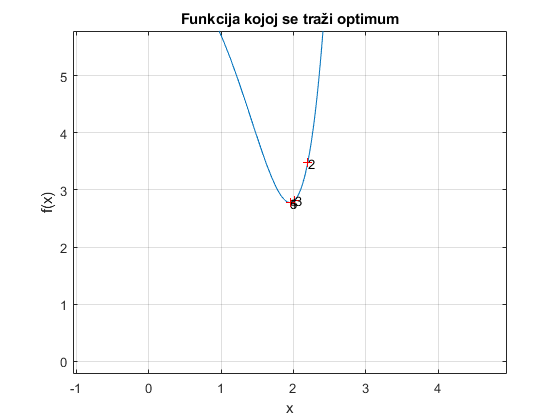

axis([X(i)-3 X(i)+3 double(vpa(subs(fsym,x,X(i))))-3 double(vpa(subs(fsym,x,X(i))))+3])

fprintf('Za pronaći još mogućih optimuma na intervalu od 0 do 5,\npotrebno je generirati novu početnu točku x0 sa "rand"\nili unijeti iznos ručno.')

Za pronaći još mogućih optimuma na intervalu od 0 do 5,
potrebno je generirati novu početnu točku x0 sa "rand"
ili unijeti iznos ručno.